# 磁定位定向算法仿真

## 基于单磁偶极子模型获取传感器读数

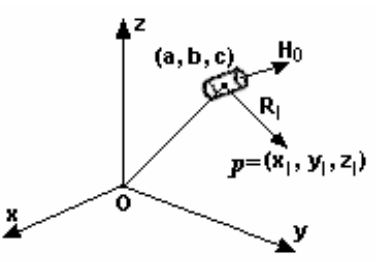

        空间点$\mathit{\mathbf{p}}$处的磁通密度（磁感应强度）：


$$$$
\mathbf{B}=\frac{\mu _r\mu _0M_T}{4\pi}\left( \frac{3\left( \mathbf{H}_0\cdot \mathbf{P} \right) \mathbf{P}}{R_{l}^{5}}-\frac{\mathbf{H}_0}{R_{l}^{3}} \right) 
\\
=N_T\left( \frac{3\left( \mathbf{H}_0\cdot \mathbf{P} \right) \mathbf{P}}{R_{l}^{5}}-\frac{\mathbf{H}_0}{R_{l}^{3}} \right) 
$$
$$


- 永磁体长度$L$

- 永磁体直径$b$

- 永磁体上下底面磁化强度$M=M_0$(A/m)

- 
$$M_T =\pi b^2 {\textrm{LM}}_0$$


- 
$$N_T =\frac{\mu_r \mu_0 M_T }{4\pi }$$


- 永磁体位置指向空间点$\mathit{\mathbf{p}}$的矢量$P$

- 永磁体位置$\left\lbrack \begin{array}{c}
a\\
b\\
c
\end{array}\right\rbrack$

- 永磁体朝向的归一化矢量${\mathit{\mathbf{H}}}_0 =\left\lbrack \begin{array}{c}
m\\
n\\
p
\end{array}\right\rbrack$

- 空间点$\mathit{\mathbf{p}}=\left\lbrack \begin{array}{c}
x_l \\
y_l \\
z_l 
\end{array}\right\rbrack$

        假设有N个传感器，第$l$个传感器的位置为$\left\lbrack \begin{array}{c}
x_l \\
y_l \\
z_l 
\end{array}\right\rbrack ,1\le l\le N$，那么，第$l$个传感器位置处的磁通密度可以表示为：


$${\mathit{\mathbf{B}}}_l =B_{\textrm{lx}} \mathbf{i}+B_{\textrm{ly}} \mathbf{j}+B_{\textrm{lz}} \mathbf{k}\;,1\le l\le N$$


三个正交项分别为：


$$\begin{array}{l}
B_{\textrm{lx}} =N_T \left\lbrace \frac{3\left\lbrack m\left(x_l -a\right)+n\left(y_l -b\right)+p\left(z_l -c\right)\right\rbrack \left(x_l -a\right)}{R_l^5 }-\frac{m}{R_l^3 }\right\rbrace \\
B_{\textrm{ly}} =N_T \left\lbrace \frac{3\left\lbrack m\left(x_l -a\right)+n\left(y_l -b\right)+p\left(z_l -c\right)\right\rbrack \left(y_l -b\right)}{R_l^5 }-\frac{n}{R_l^3 }\right\rbrace \\
B_{\textrm{lz}} =N_T \left\lbrace \frac{3\left\lbrack m\left(x_l -a\right)+n\left(y_l -b\right)+p\left(z_l -c\right)\right\rbrack \left(z_l -c\right)}{R_l^5 }-\frac{p}{R_l^3 }\right\rbrace 
\end{array}$$



$$R_l =\sqrt{{\left(x_l -a\right)}^2 +{\left(y_l -b\right)}^2 +{\left(z_l -c\right)}^2 }$$


由于${\mathit{\mathbf{H}}}_0$是归一化矢量，有：


$$m^2 +n^2 +p^2 =1$$


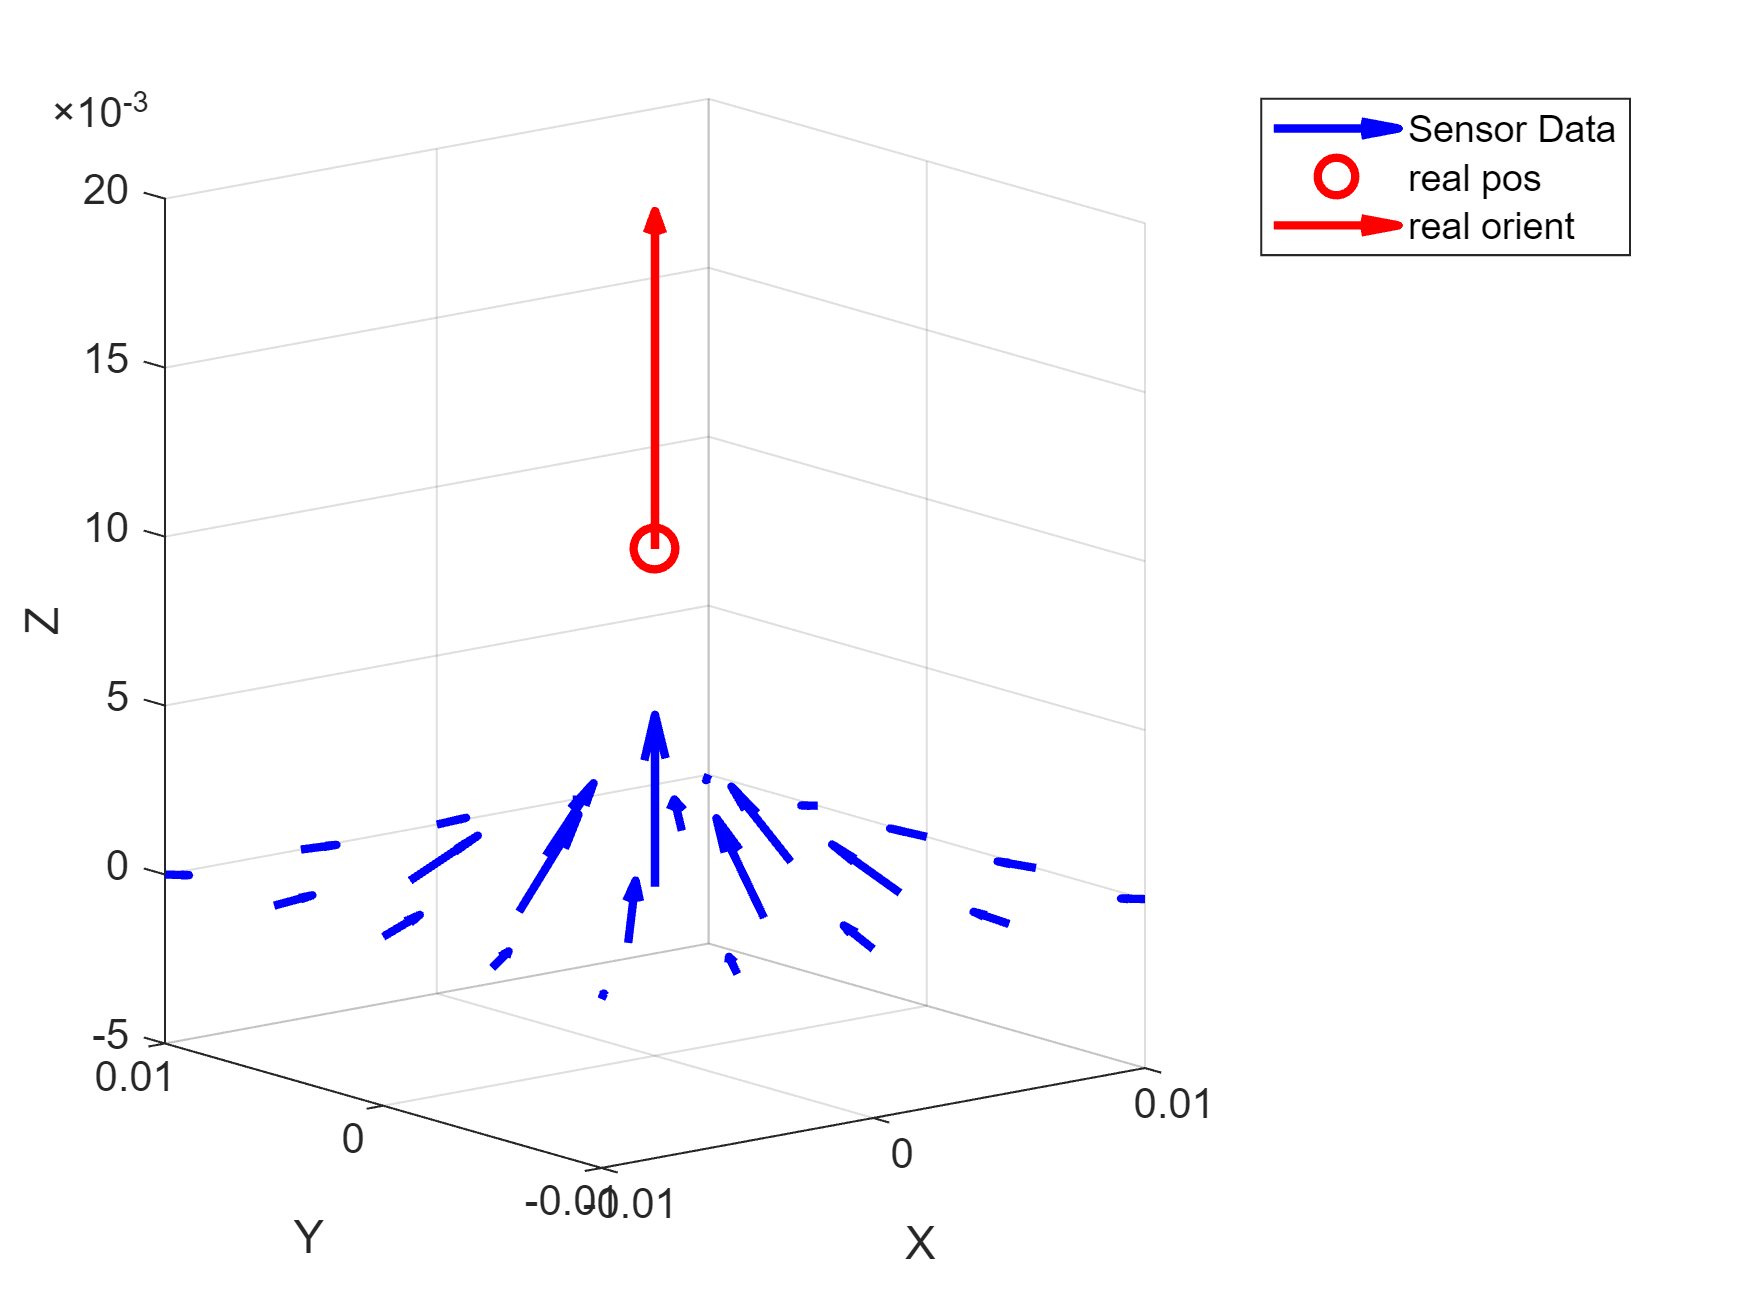

% 所有单位均采用国际单位制（SI)，坐标系采用右手系

mag_L = 0.003; % 永磁体圆柱长度
mag_b = 0.003; % 永磁体圆柱半径

N_T=1; % 系数
% 永磁体位置
a = 0;       % x
b = 0;       % y
c = 0.01;    % z
% 永磁体朝向
m = 0;
n = 0;
p = 1;
H_0 = [m;n;p];
H_0 = normalize(H_0,"norm"); % 归一化向量（按L2范数缩放）
% 传感器
sensor_n = 5; % 传感器行列数
sensor_interval = 0.005; % 传感器间隔
sensor_N = sensor_n^2; % 传感器数量N
sensor_pos = zeros(sensor_N,3); % 传感器位置
sensor_noise = 3e+02; % 传感器噪声
for i = 1:sensor_n % y
    for j = 1:sensor_n % x
        sensor_pos((i-1)*sensor_n + j,1)=((j-1)-(sensor_n-1)/2)*sensor_interval;   % x
        sensor_pos((i-1)*sensor_n + j,2)=((i-1)-(sensor_n-1)/2)*sensor_interval;   % y
        sensor_pos((i-1)*sensor_n + j,3)=0;                                        % z
    end
end

Bl = zeros(sensor_N,3);
% 磁通密度
for i = 1:sensor_N
   [Bl(i,1),Bl(i,2),Bl(i,3)] = MagneticFluxDensityComponent(N_T,H_0(1),H_0(2),H_0(3),a,b,c,sensor_pos(i,1),sensor_pos(i,2),sensor_pos(i,3),sensor_noise); 
end

% 画出各个传感器获得的磁通密度矢量
figure;
quiver3(sensor_pos(:,1),sensor_pos(:,2),sensor_pos(:,3),Bl(:,1),Bl(:,2),Bl(:,3),'-b','LineWidth',2);
hold on;
% [X,Y,Z]=cylinder(mag_b/2);
% X=X+a;
% Y=Y+b;
% Z=Z*mag_L+c;
% s = surf(X,Y,Z);

plot3(a,b,c,'or','MarkerSize',10,'LineWidth',2);
quiver3(a,b,c,m,n,p,0.01,'-r','LineWidth',2);

view([-38.7551 10.6989]);
xlabel('X');
ylabel('Y');
zlabel('Z');
legend('Sensor Data','real pos','real orient');
hold off;

% test = target_function([0 0 1 0 0 0.03],sensor_pos,Bl,N_T)
init = [0 0 1 0 0 0.05];
lb = []; % 上界
ub = []; % 下界
predict = lsqnonlin(@(param) target_function(param,sensor_pos,Bl,N_T),init,lb,ub,[],[],[],[],@nlcon)


找到目标函数值更低的可行点。


找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


predict =    -0.0005   -0.0016    1.0000   -0.0000   -0.0000    0.0100


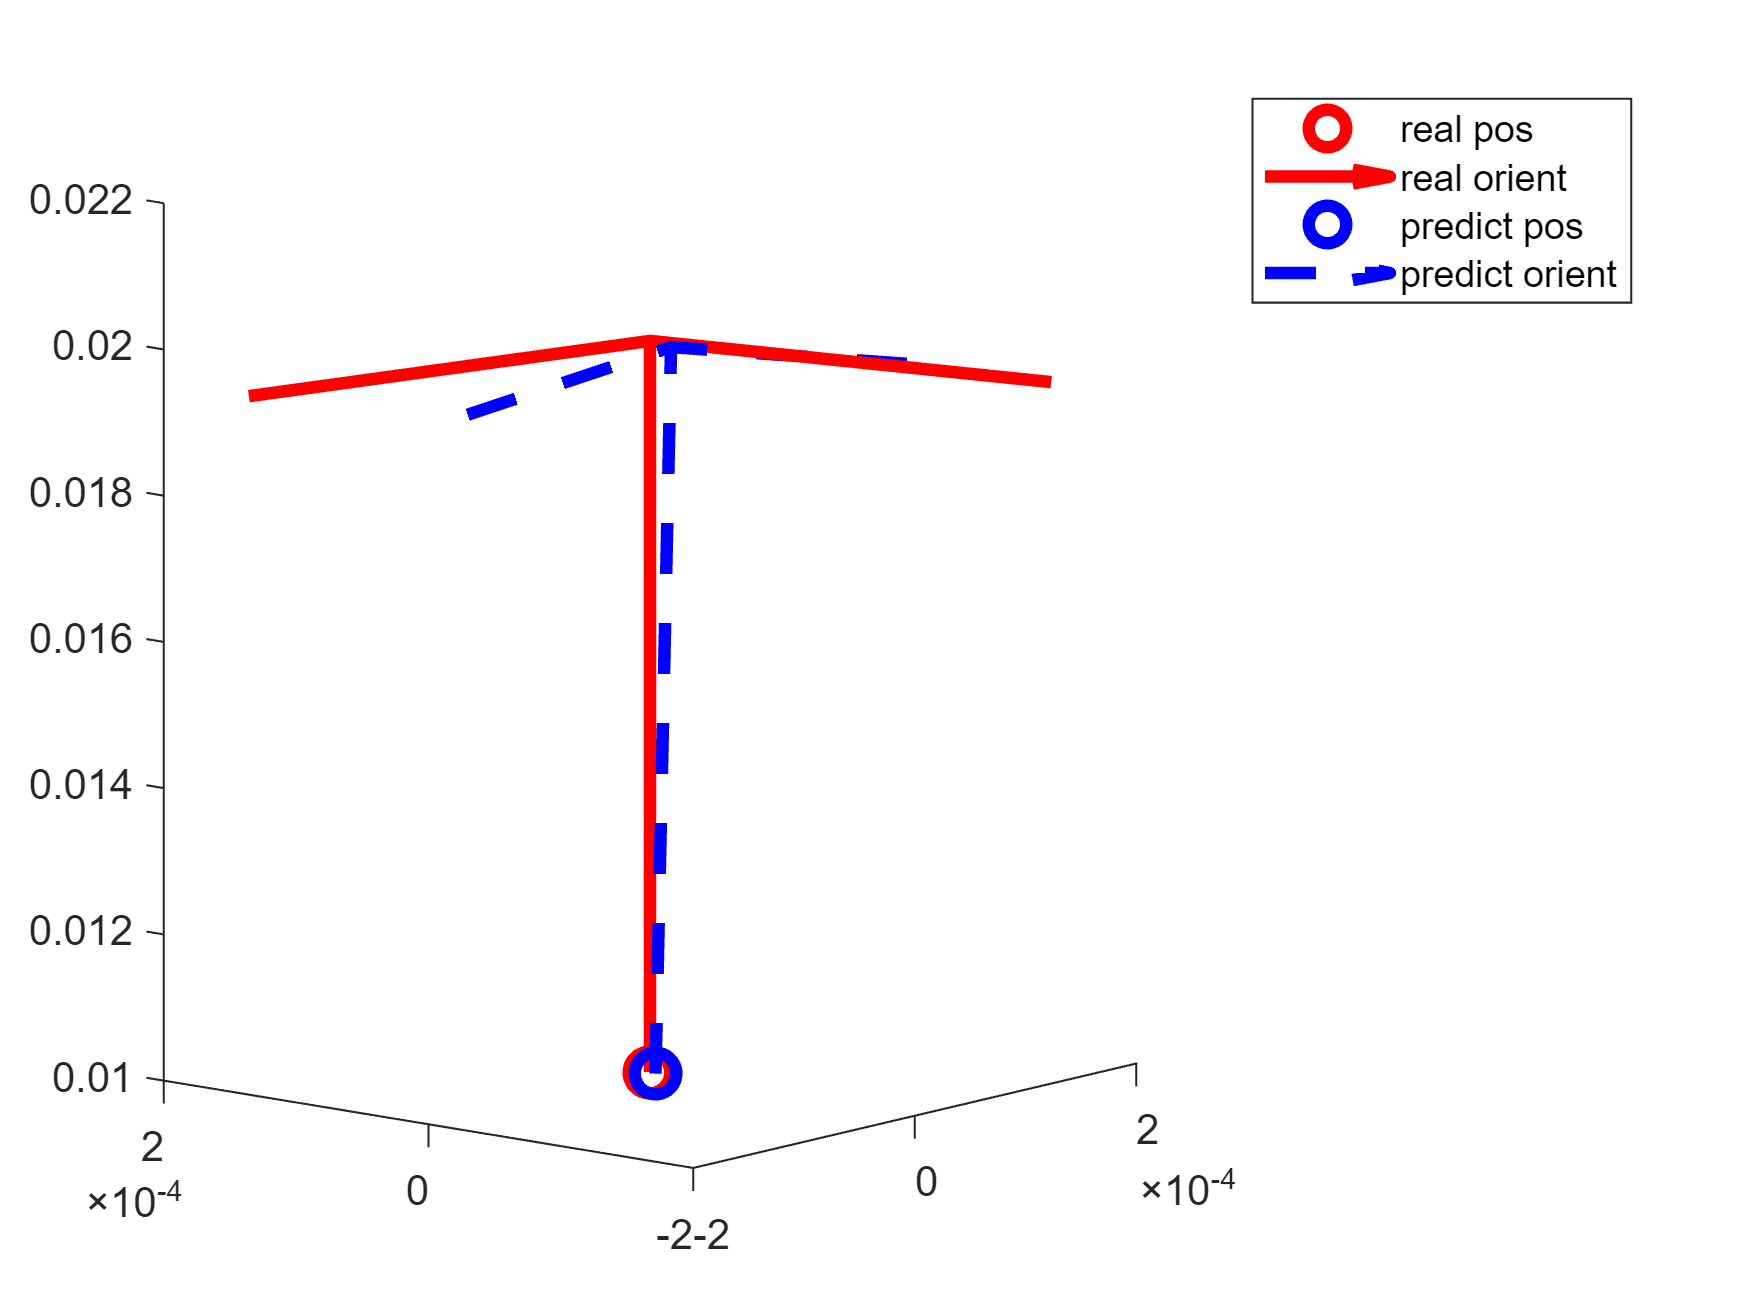

% 比较磁铁真实位置与预测位置
figure;
plot3(a,b,c,'or','MarkerSize',10,'LineWidth',3);
hold on;
quiver3(a,b,c,m,n,p,0.01,'-r','LineWidth',3);

plot3(predict(4),predict(5),predict(6),'ob','MarkerSize',10,'LineWidth',3);
quiver3(predict(4),predict(5),predict(6),predict(1),predict(2),predict(3),0.01,'--b','LineWidth',3);

legend('real pos','real orient','predict pos','predict orient');
view([-50.0849 8.8183]);
hold off;

function [Blx, Bly, Blz] = MagneticFluxDensityComponent(N_T,m,n,p,a,b,c,x,y,z,noise)
rng default % 为了可重复性，设置默认随机数种子

Rl = sqrt((x-a)^2+(y-b)^2+(z-c)^2);
comm = 3*(m*(x-a)+n*(y-b)+p*(z-c));
Blx = N_T*((comm*(x-a))/(Rl^5)-m/(Rl^3)) + noise*randn;
Bly = N_T*((comm*(y-b))/(Rl^5)-n/(Rl^3)) + noise*randn;
Blz = N_T*((comm*(z-c))/(Rl^5)-p/(Rl^3)) + noise*randn;
end

function F = target_function(param,sensor_pos,Bl,N_T)
m = param(1);
n = param(2);
p = param(3);
a = param(4);
b = param(5);
c = param(6);
N = size(sensor_pos,1);
Bpre = zeros(N,3);
for i = 1:N
    [Bpre(i,1),Bpre(i,2),Bpre(i,3)] = MagneticFluxDensityComponent(N_T,m,n,p,a,b,c,sensor_pos(i,1),sensor_pos(i,2),sensor_pos(i,3),0);
    F((i-1)*3 + 1) = Bpre(i,1) - Bl(i,1);
    F((i-1)*3 + 2) = Bpre(i,2) - Bl(i,2);
    F((i-1)*3 + 3) = Bpre(i,3) - Bl(i,3);
end
end

function [c,ceq] = nlcon(param)
c = [];

m = param(1);
n = param(2);
p = param(3);
ceq = m^2 + n^2 + p^2 - 1;
end